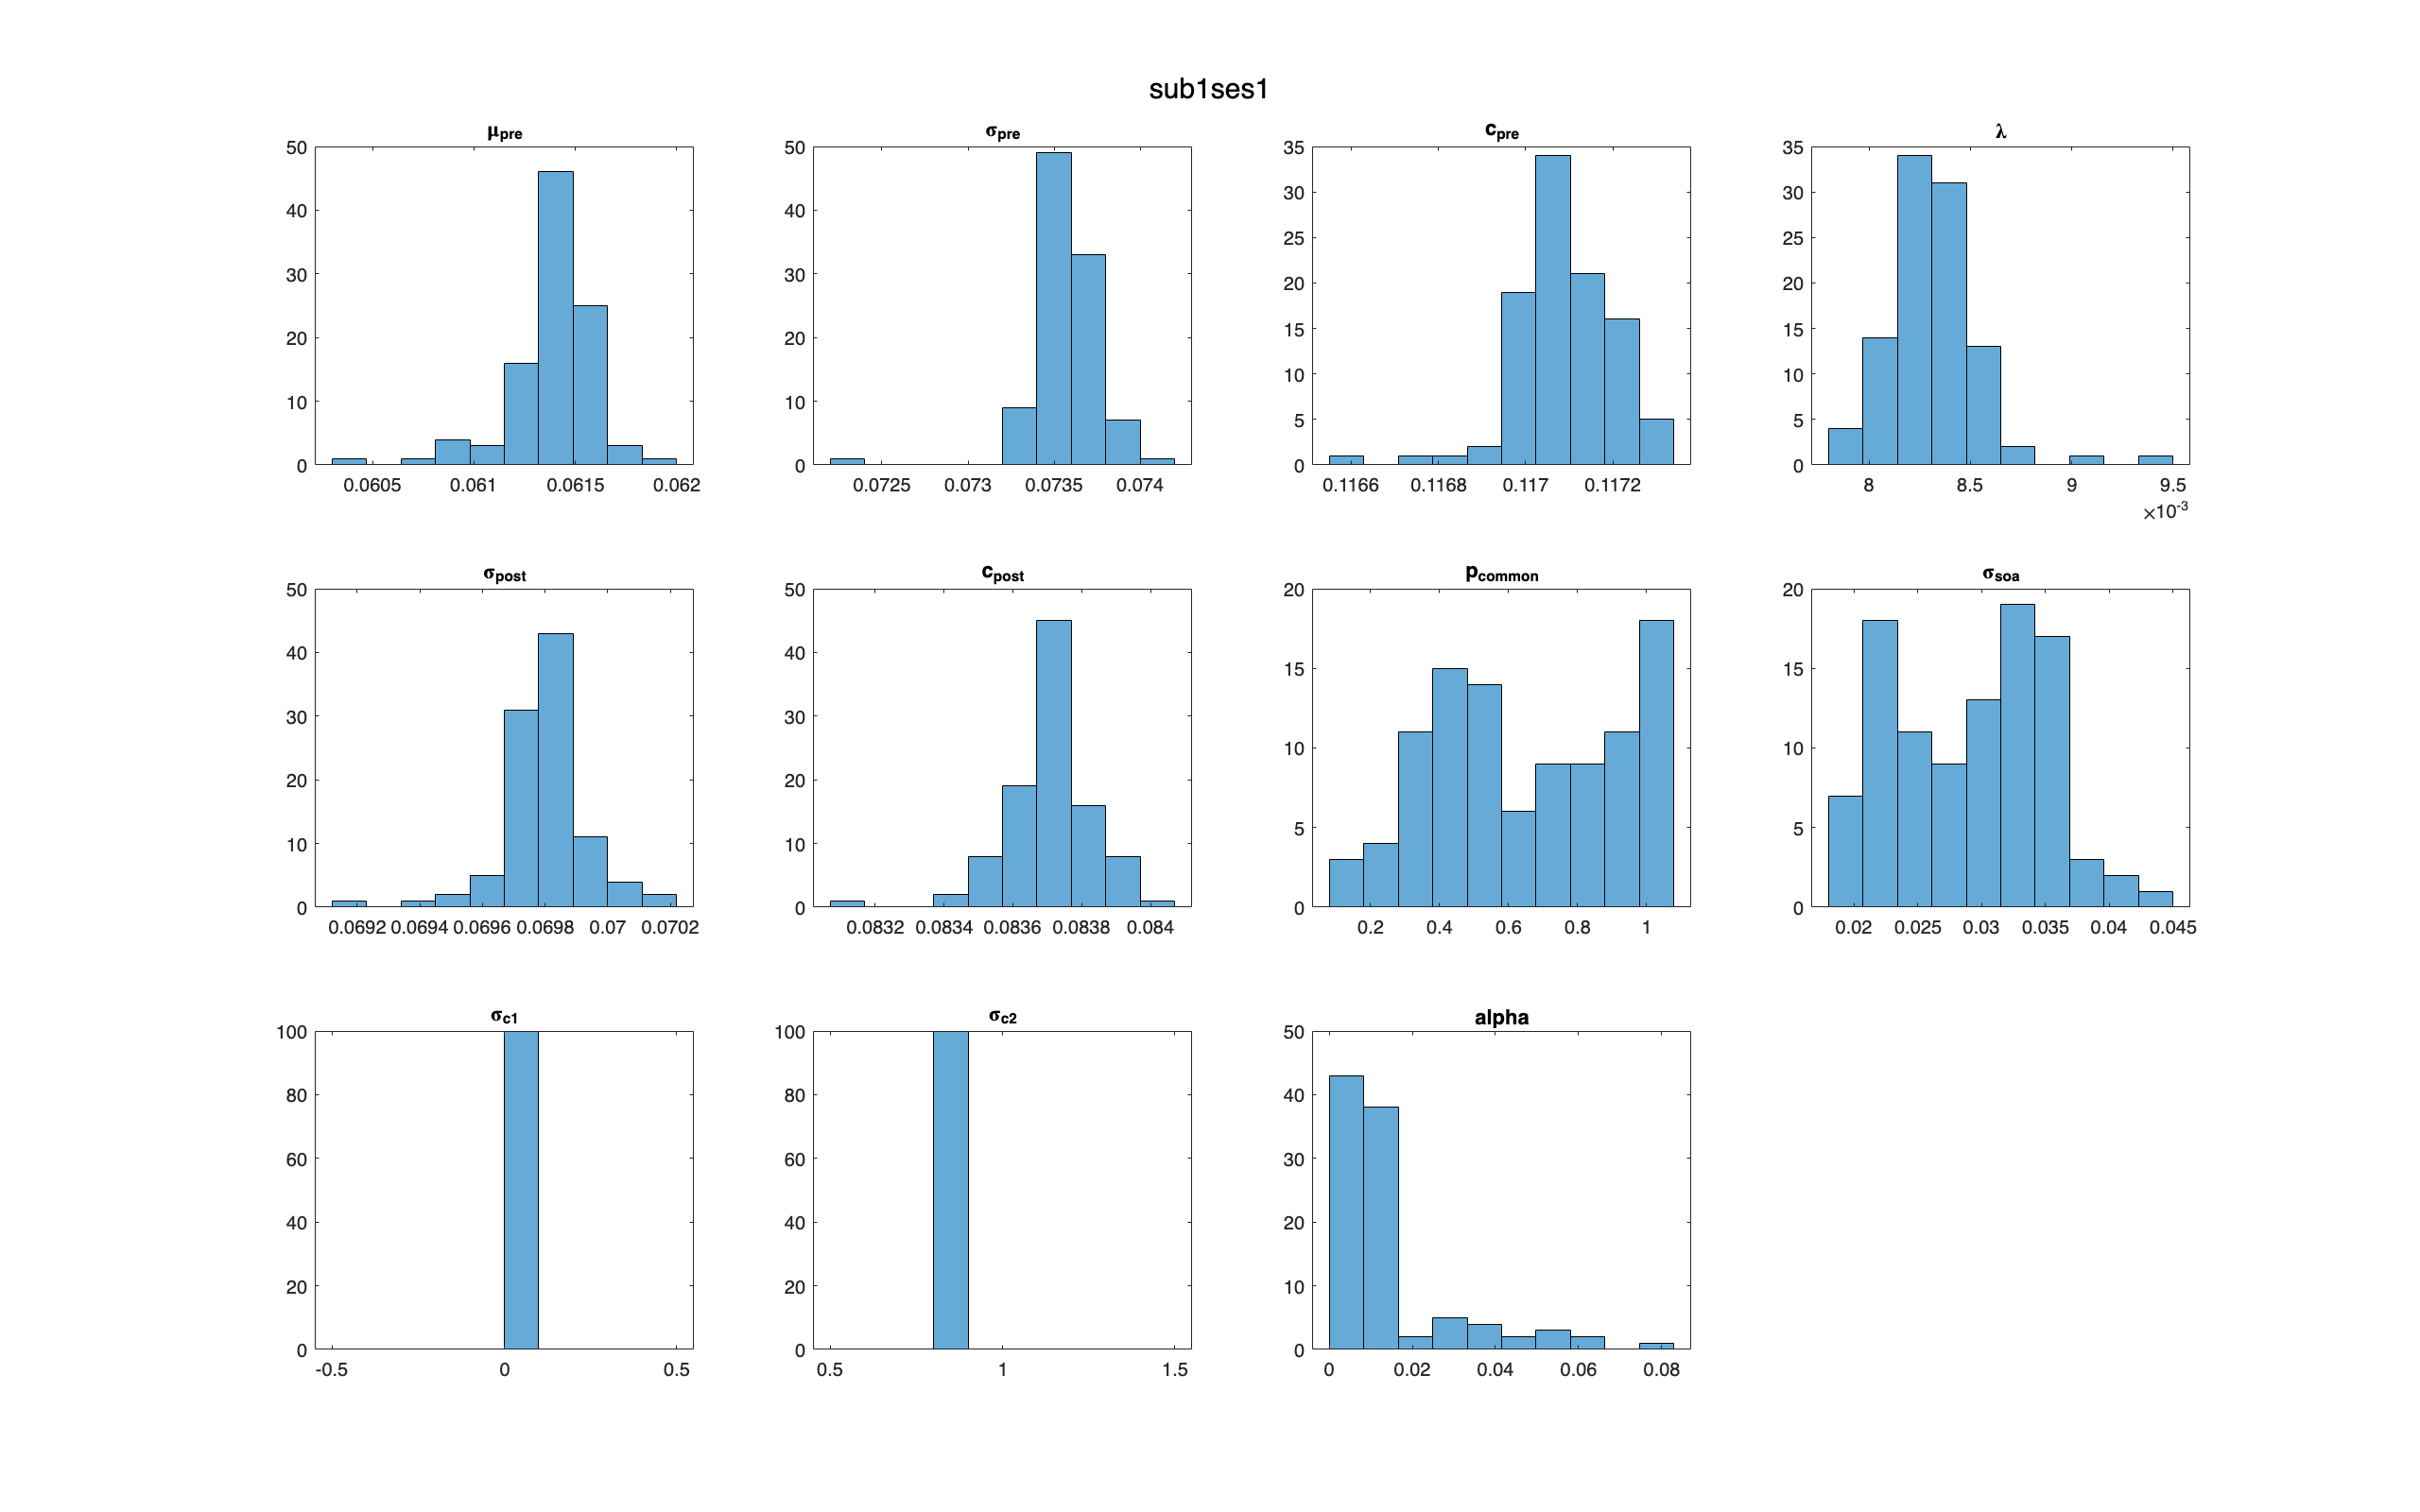

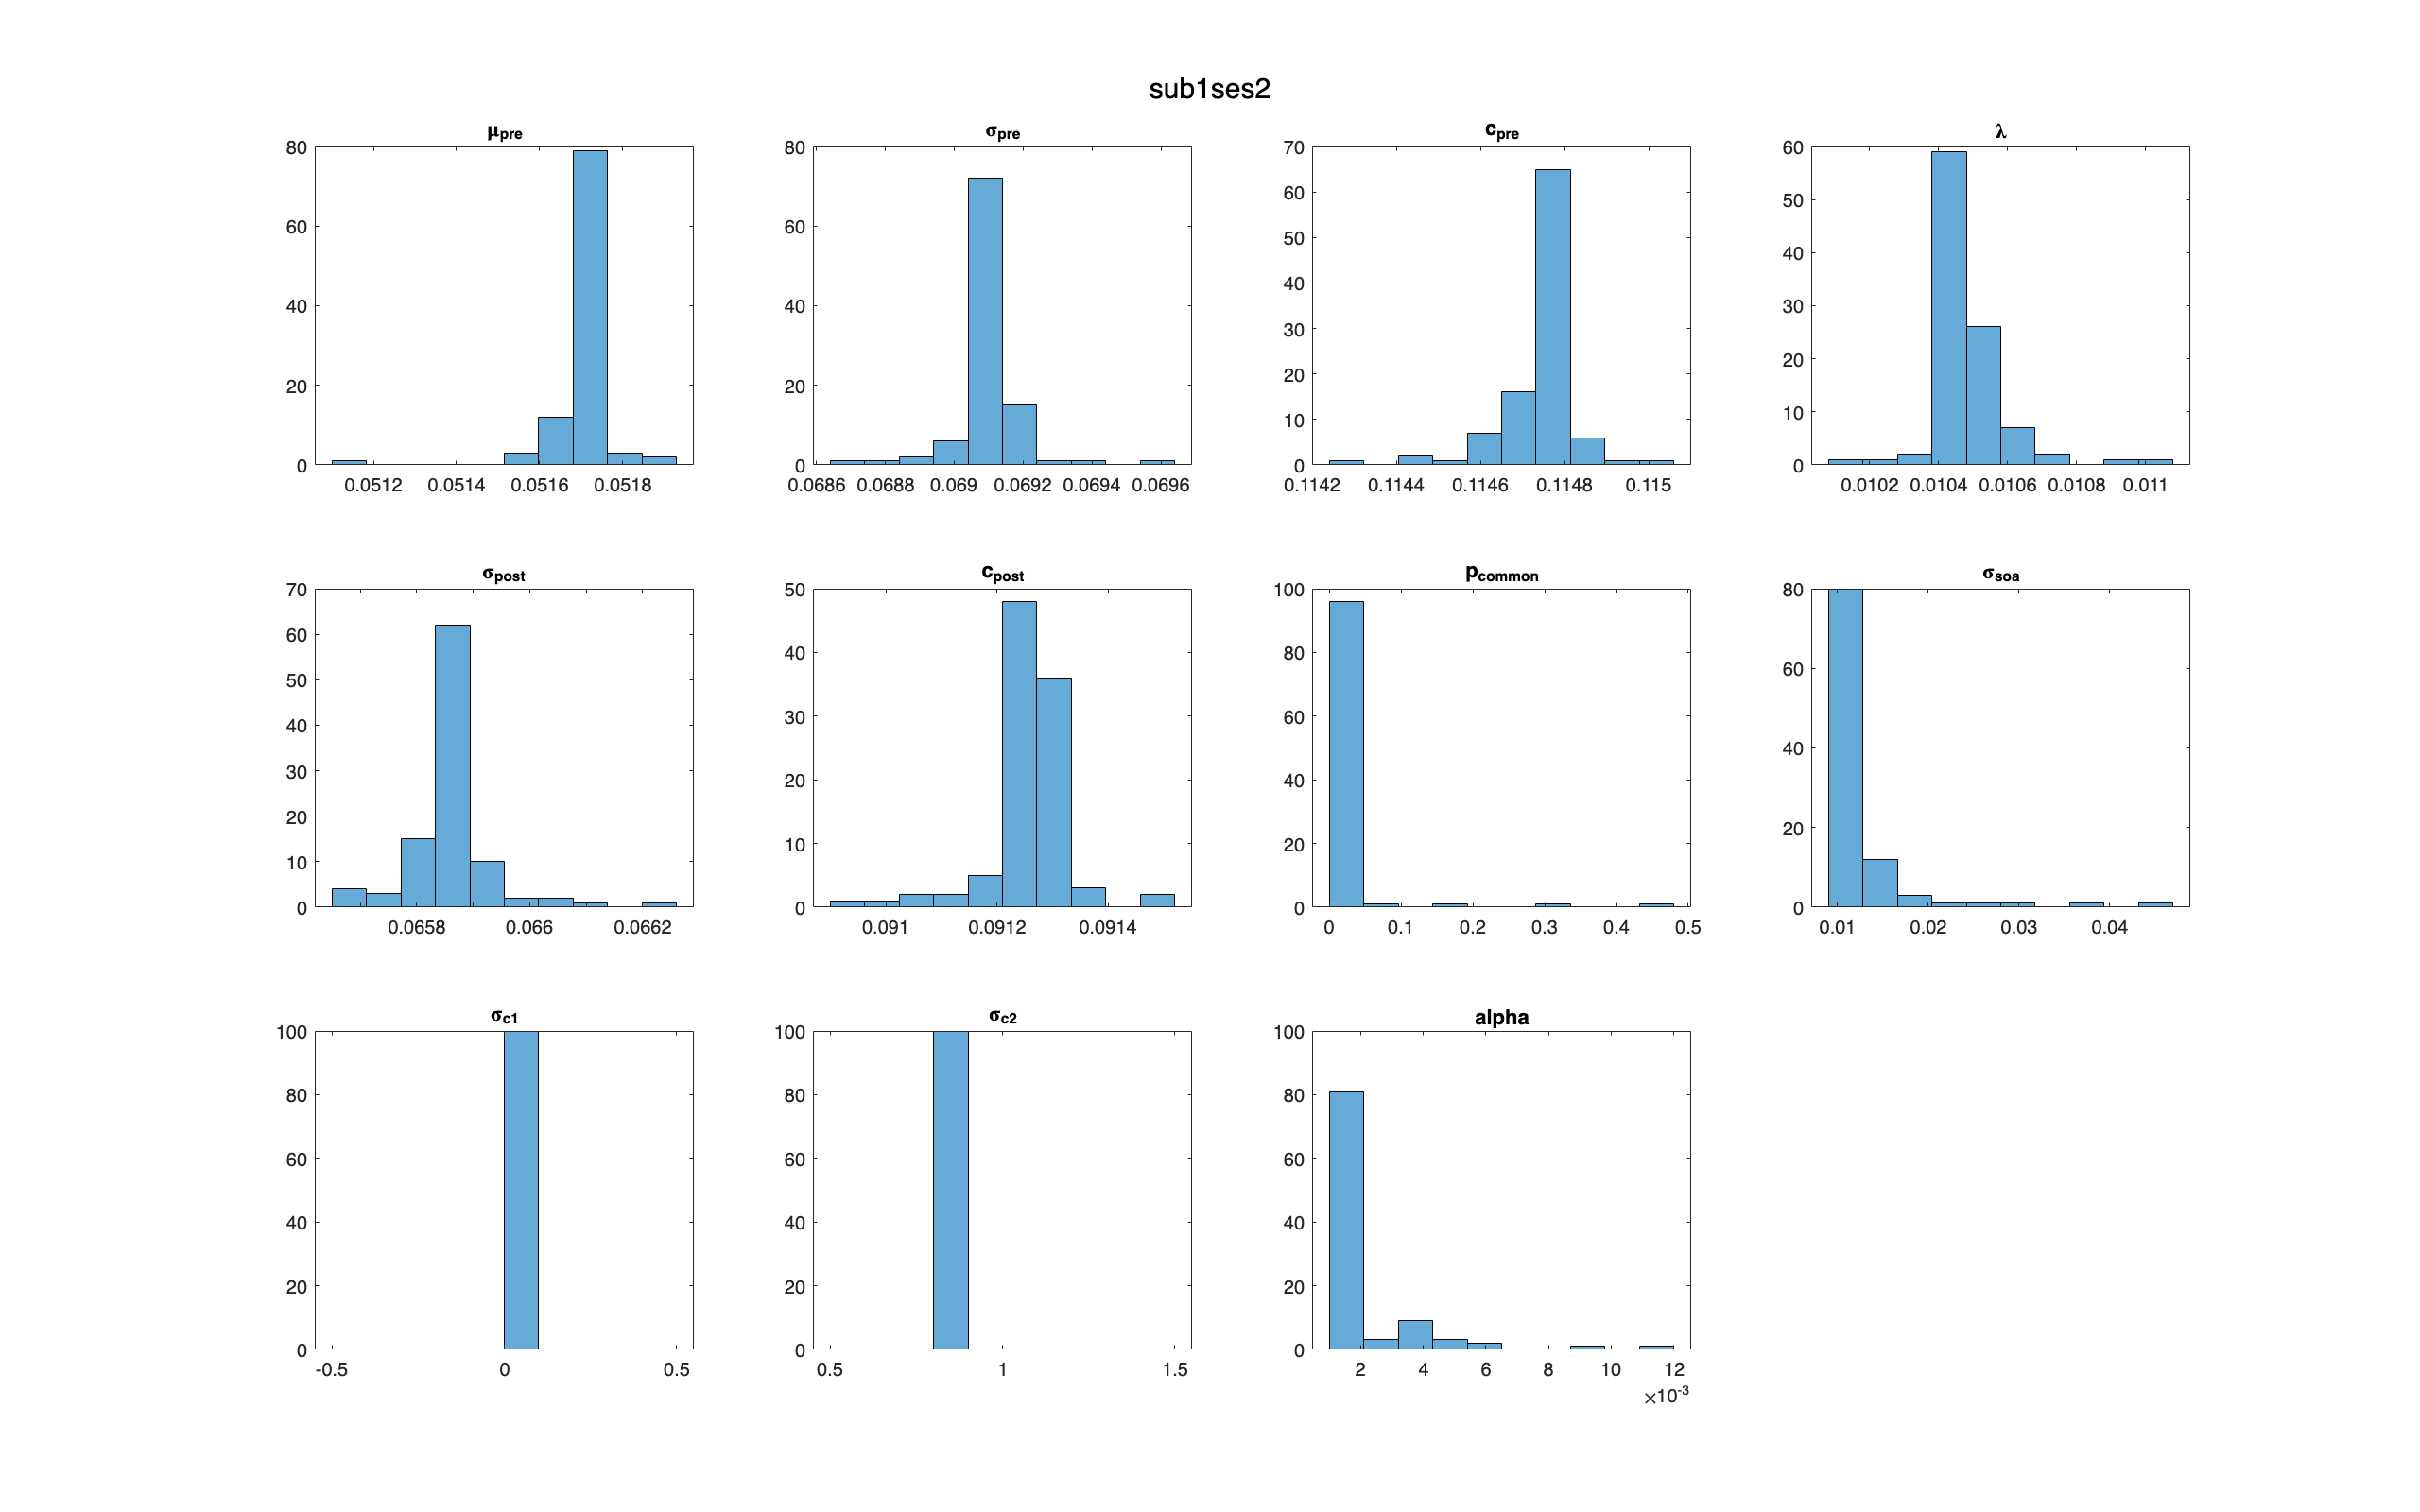

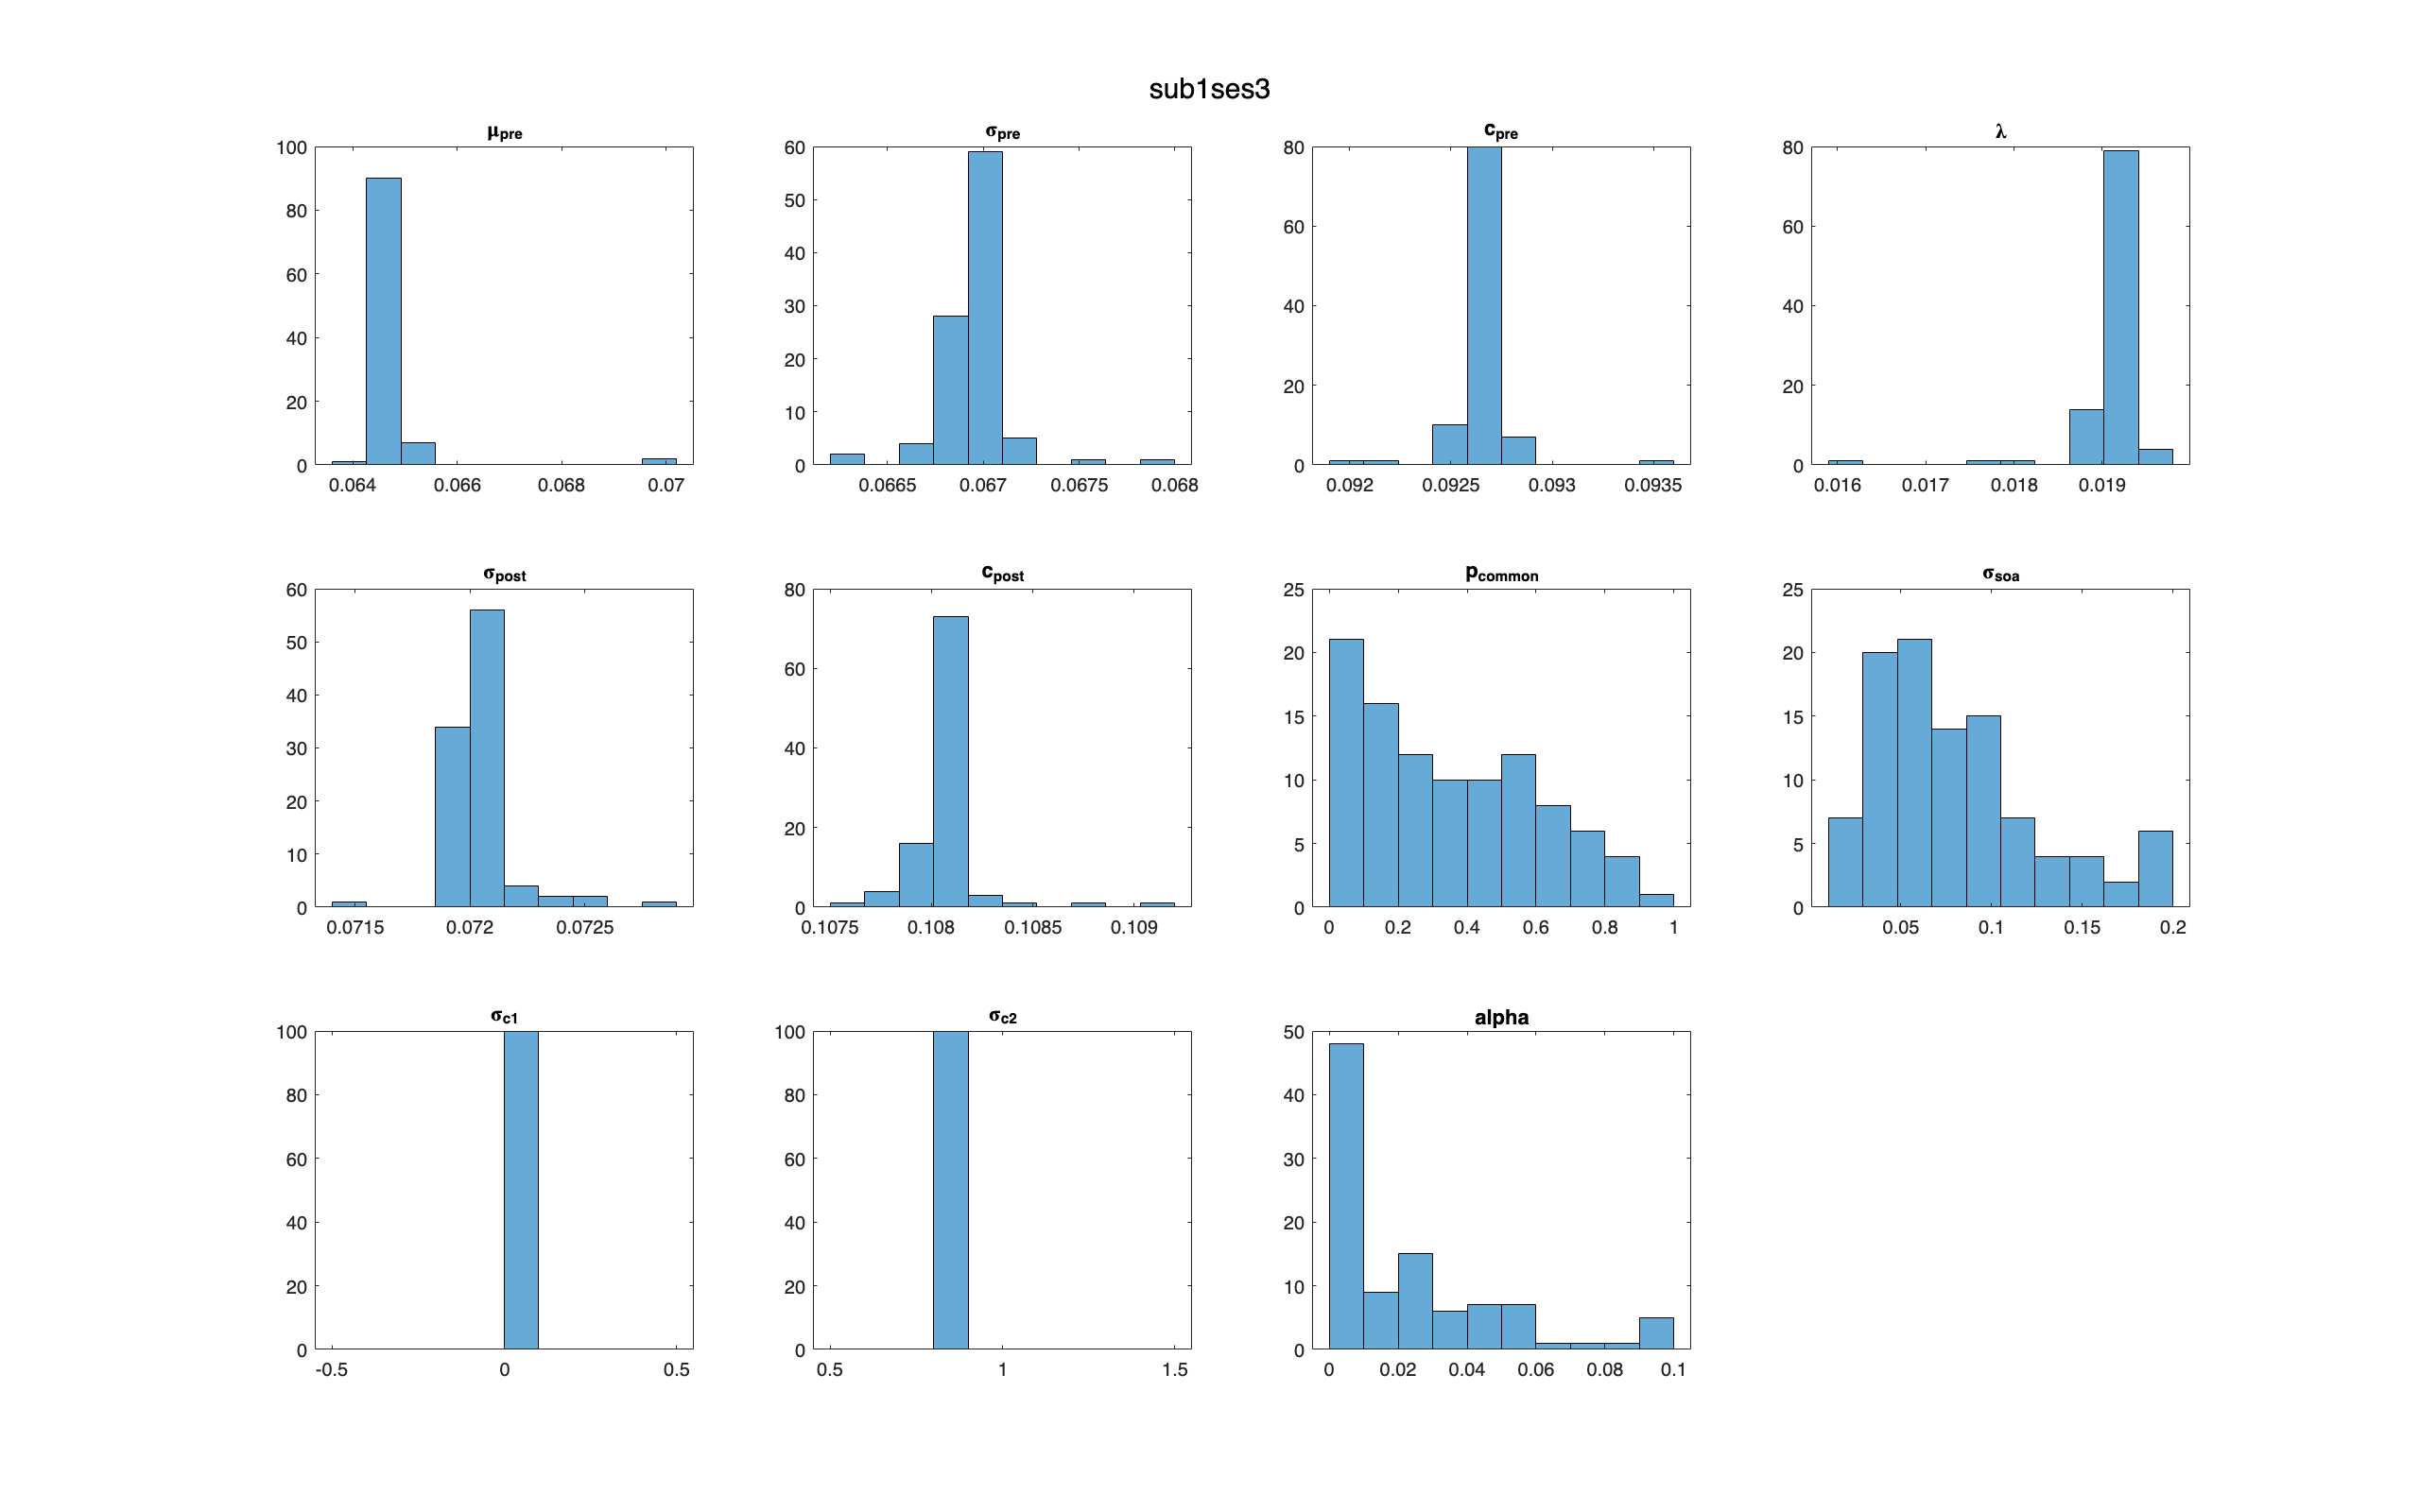

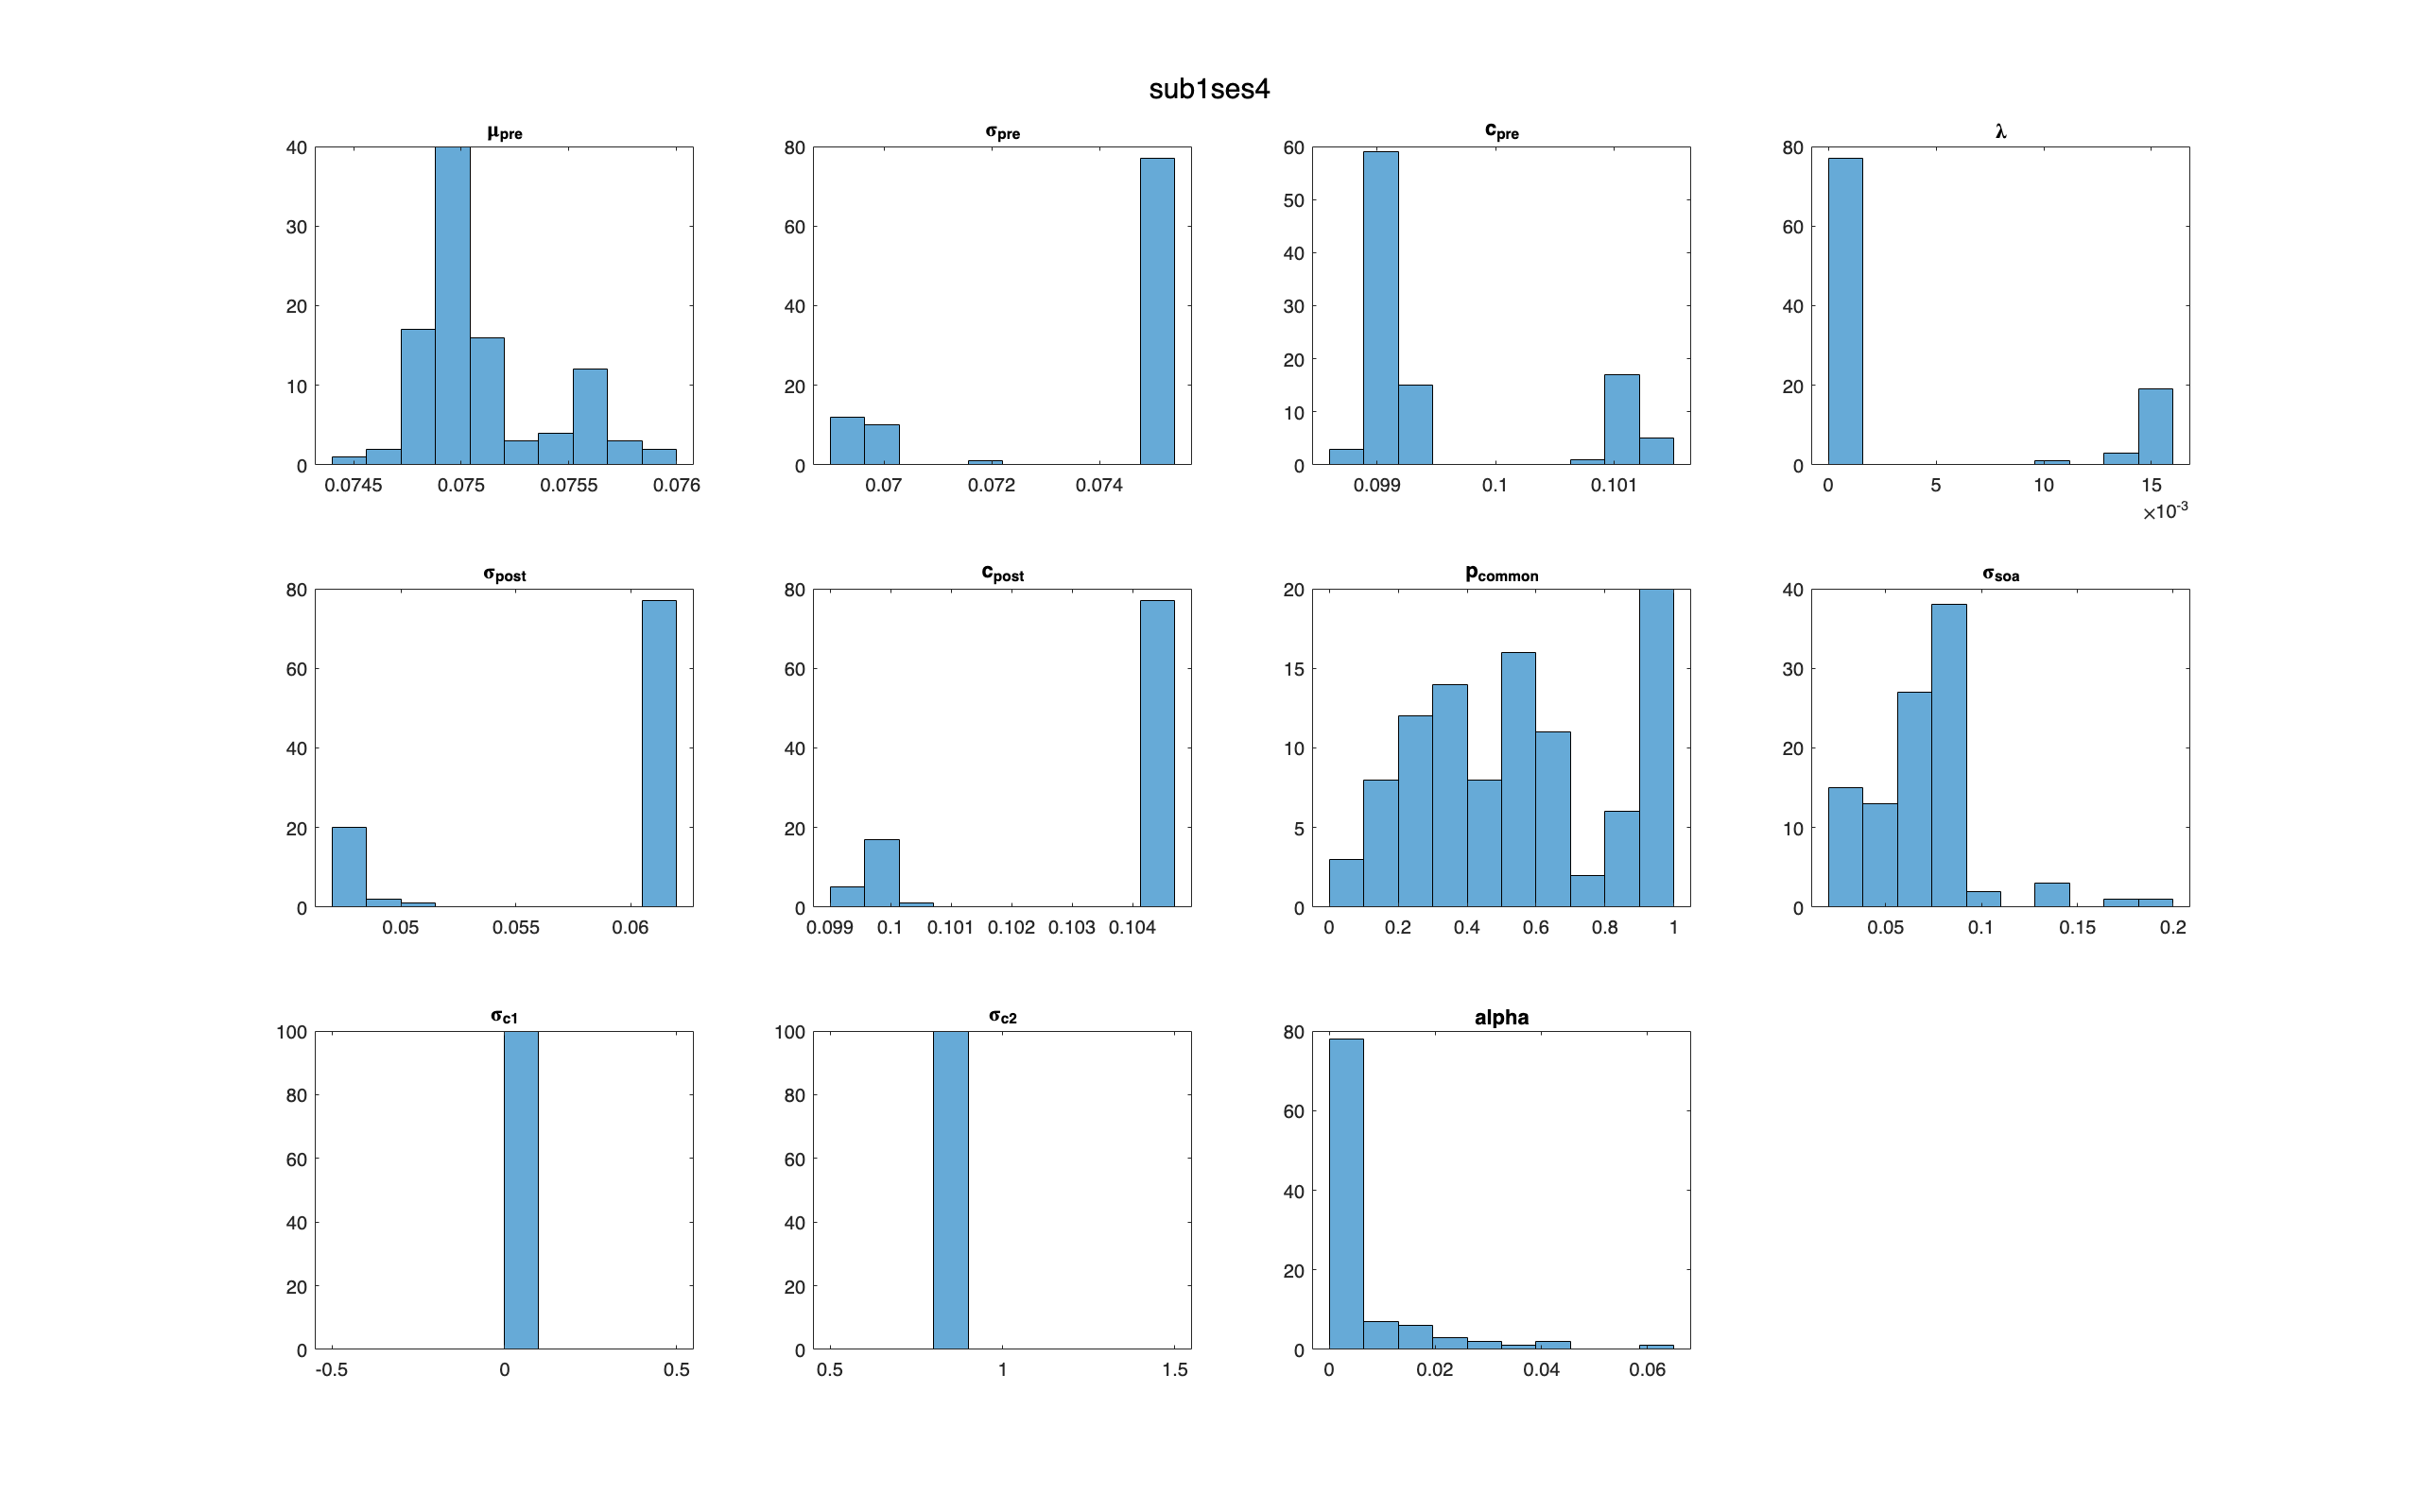

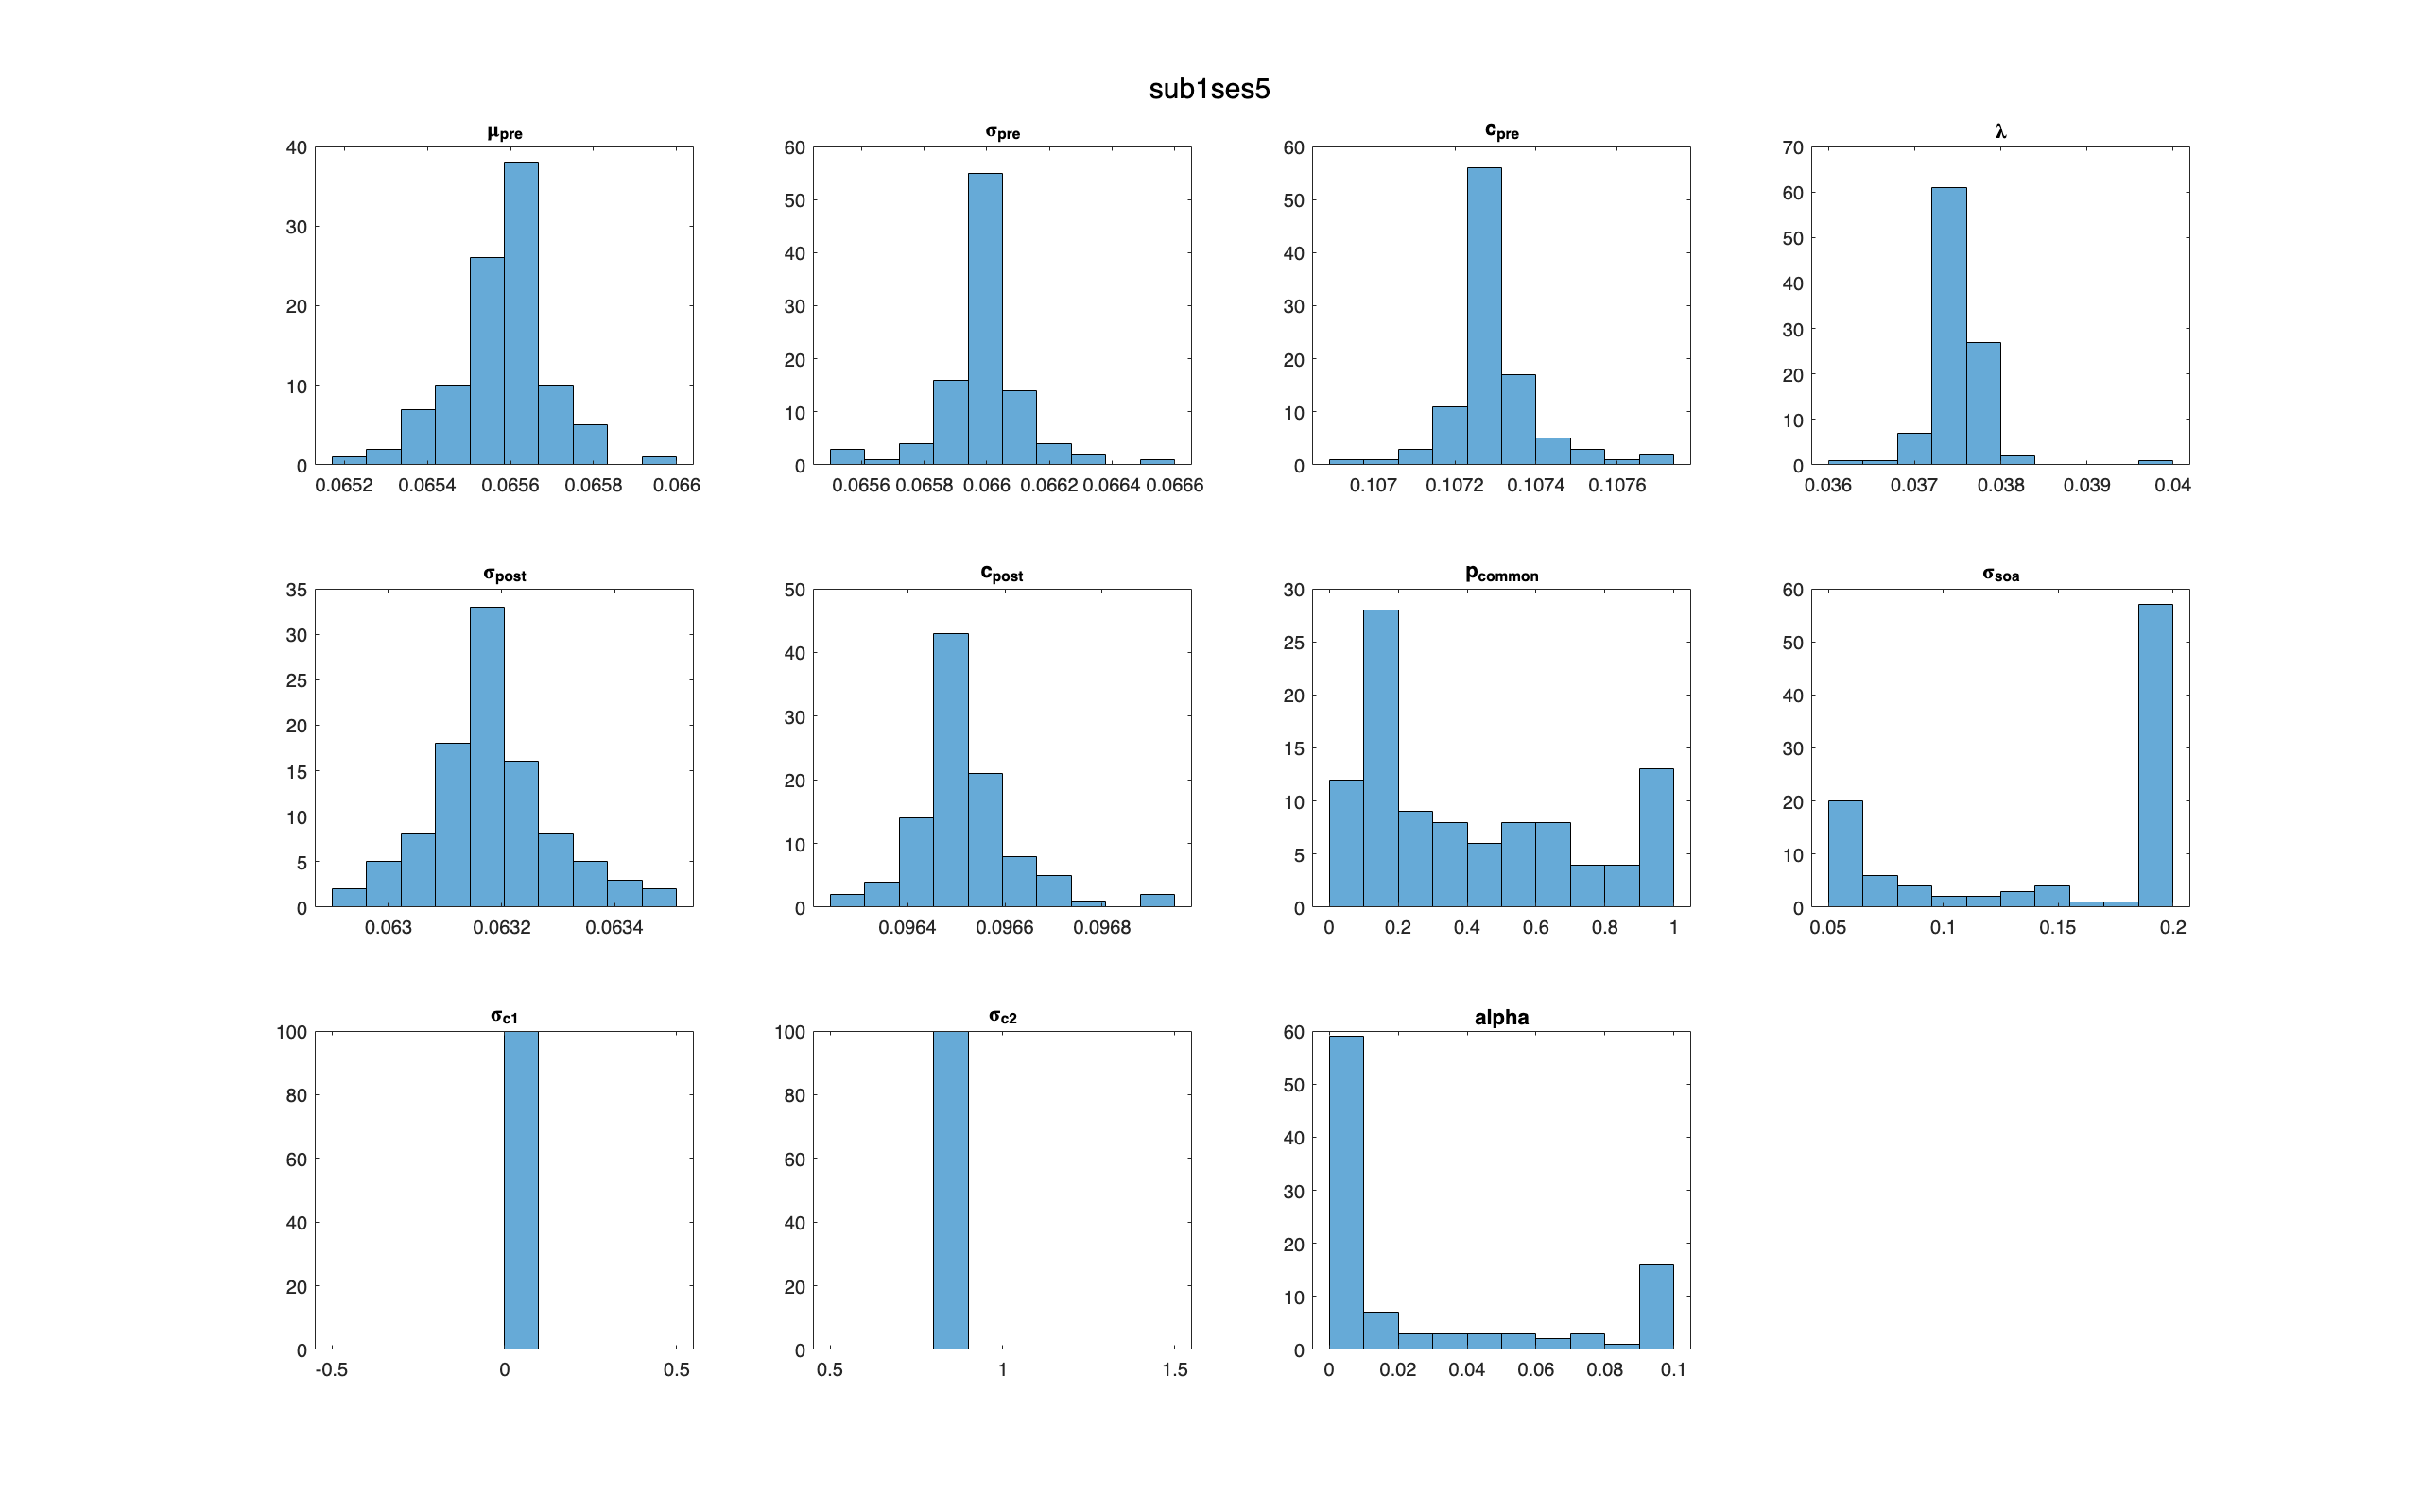

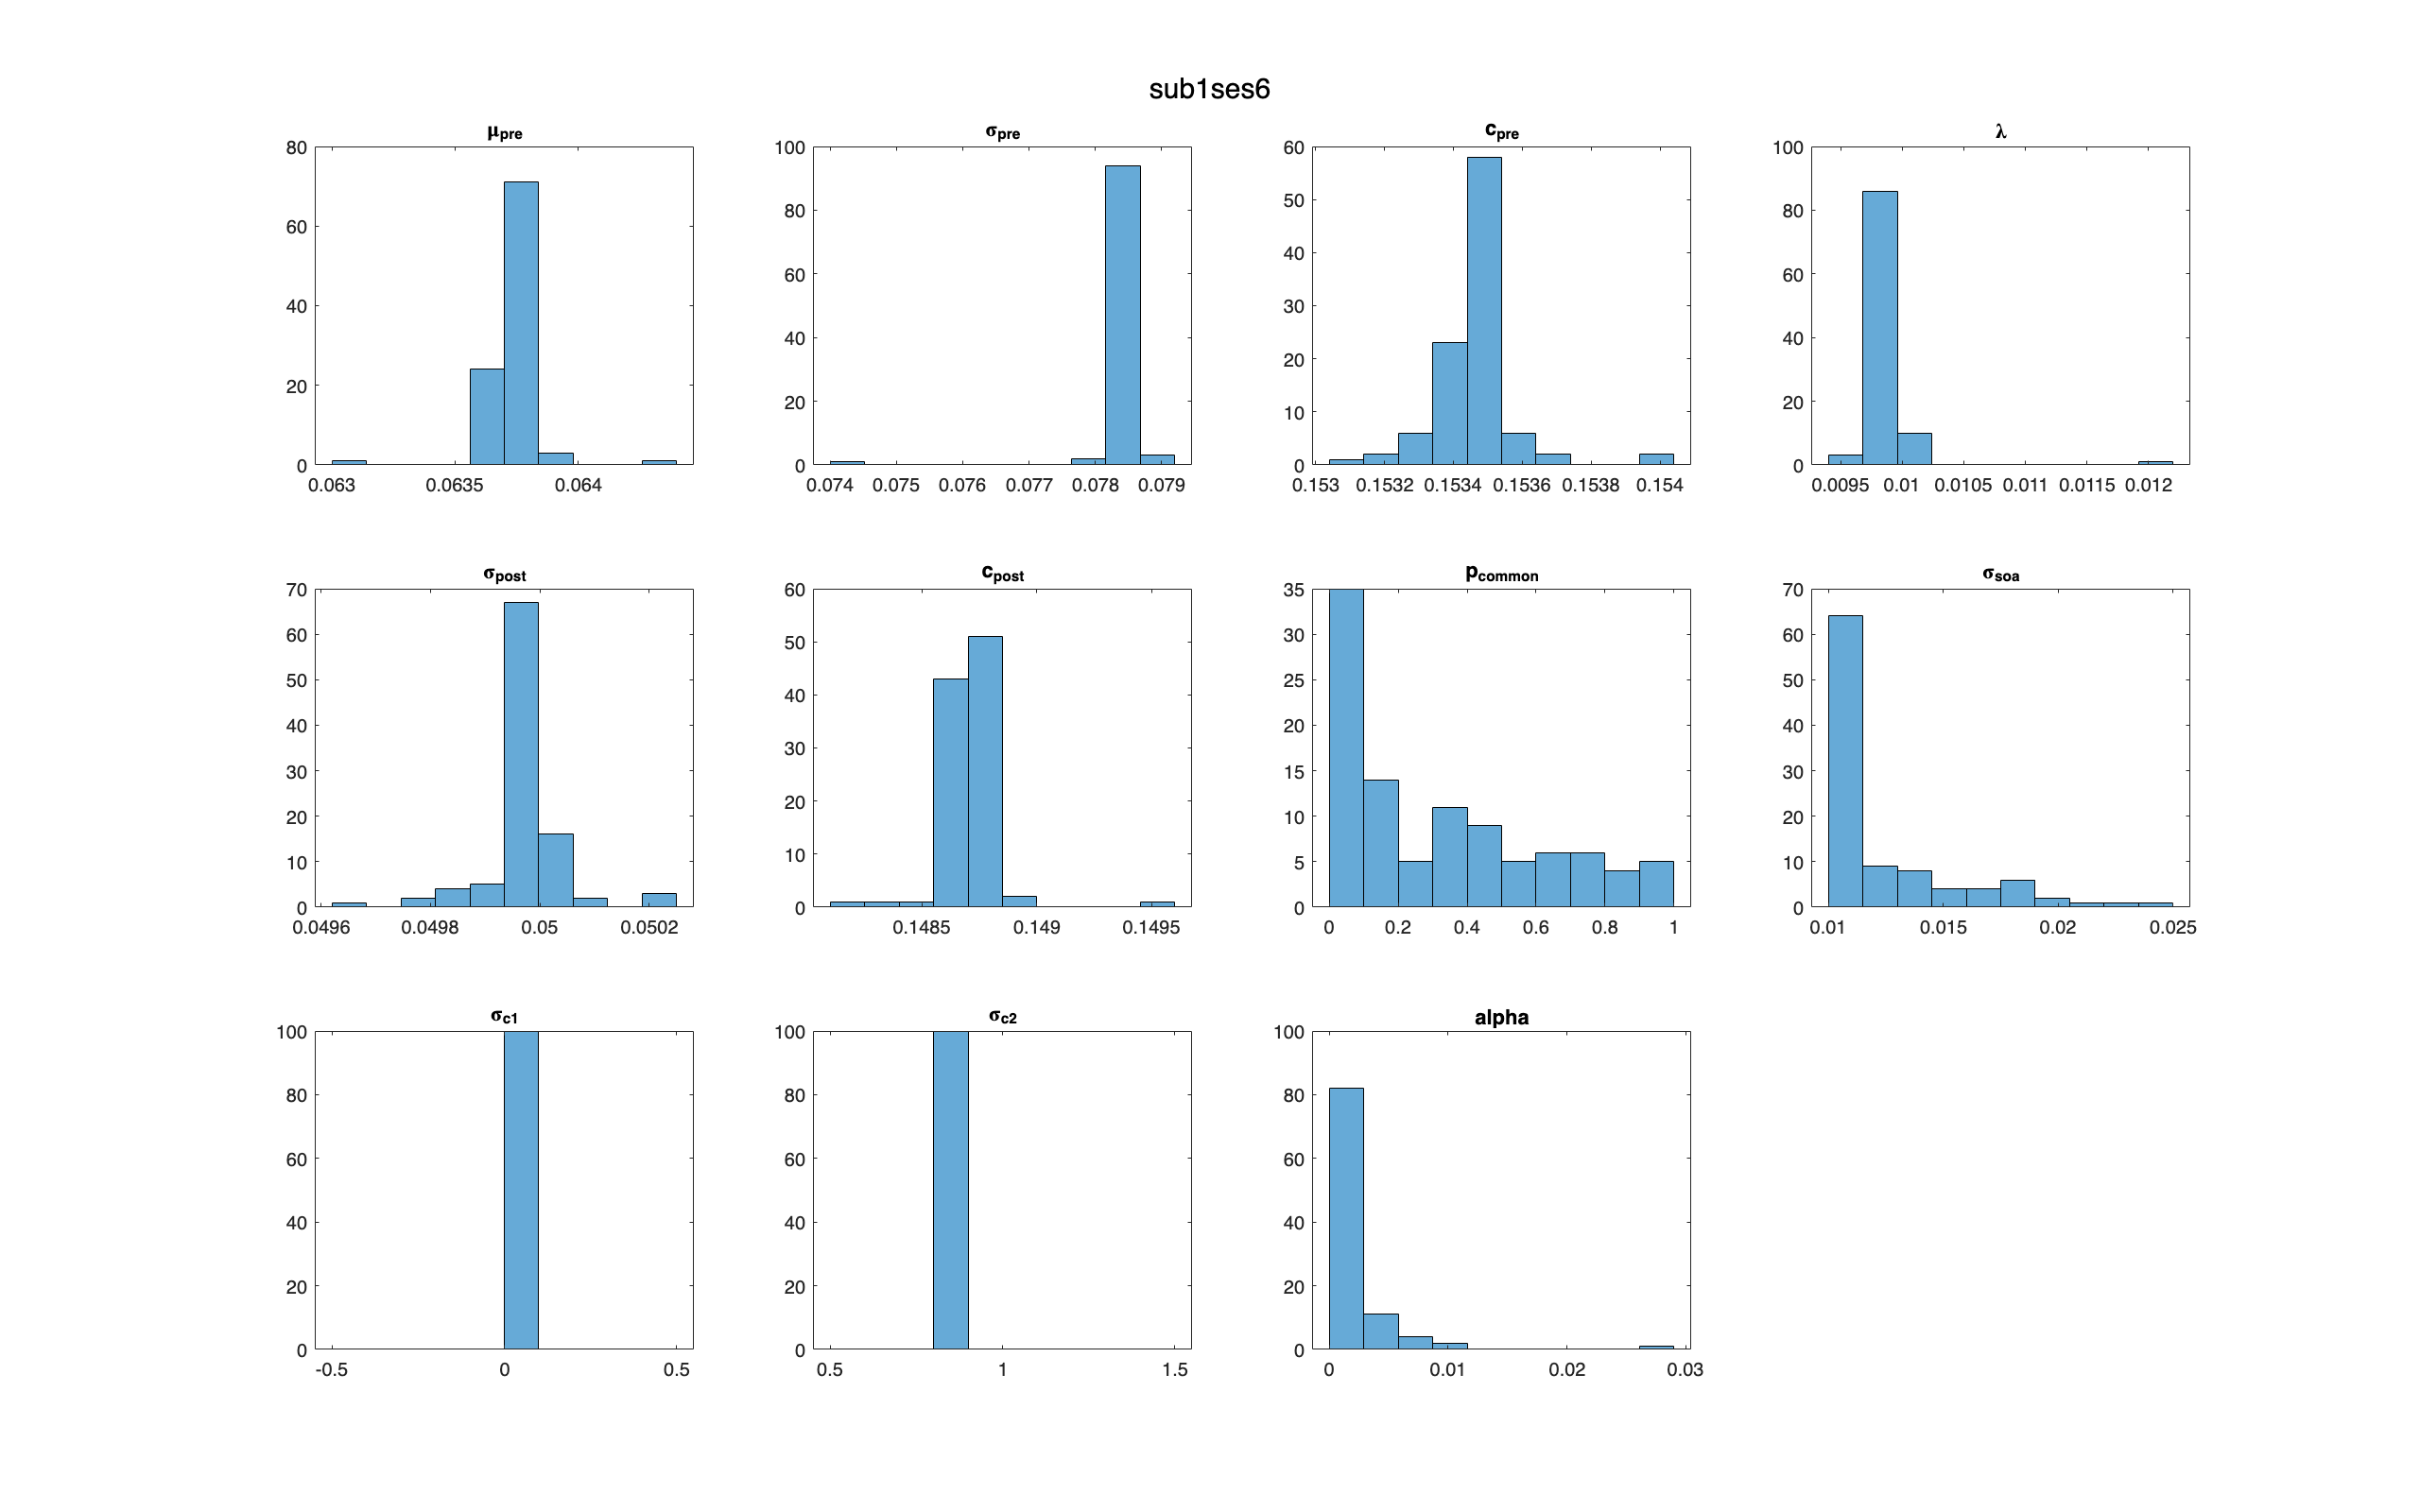

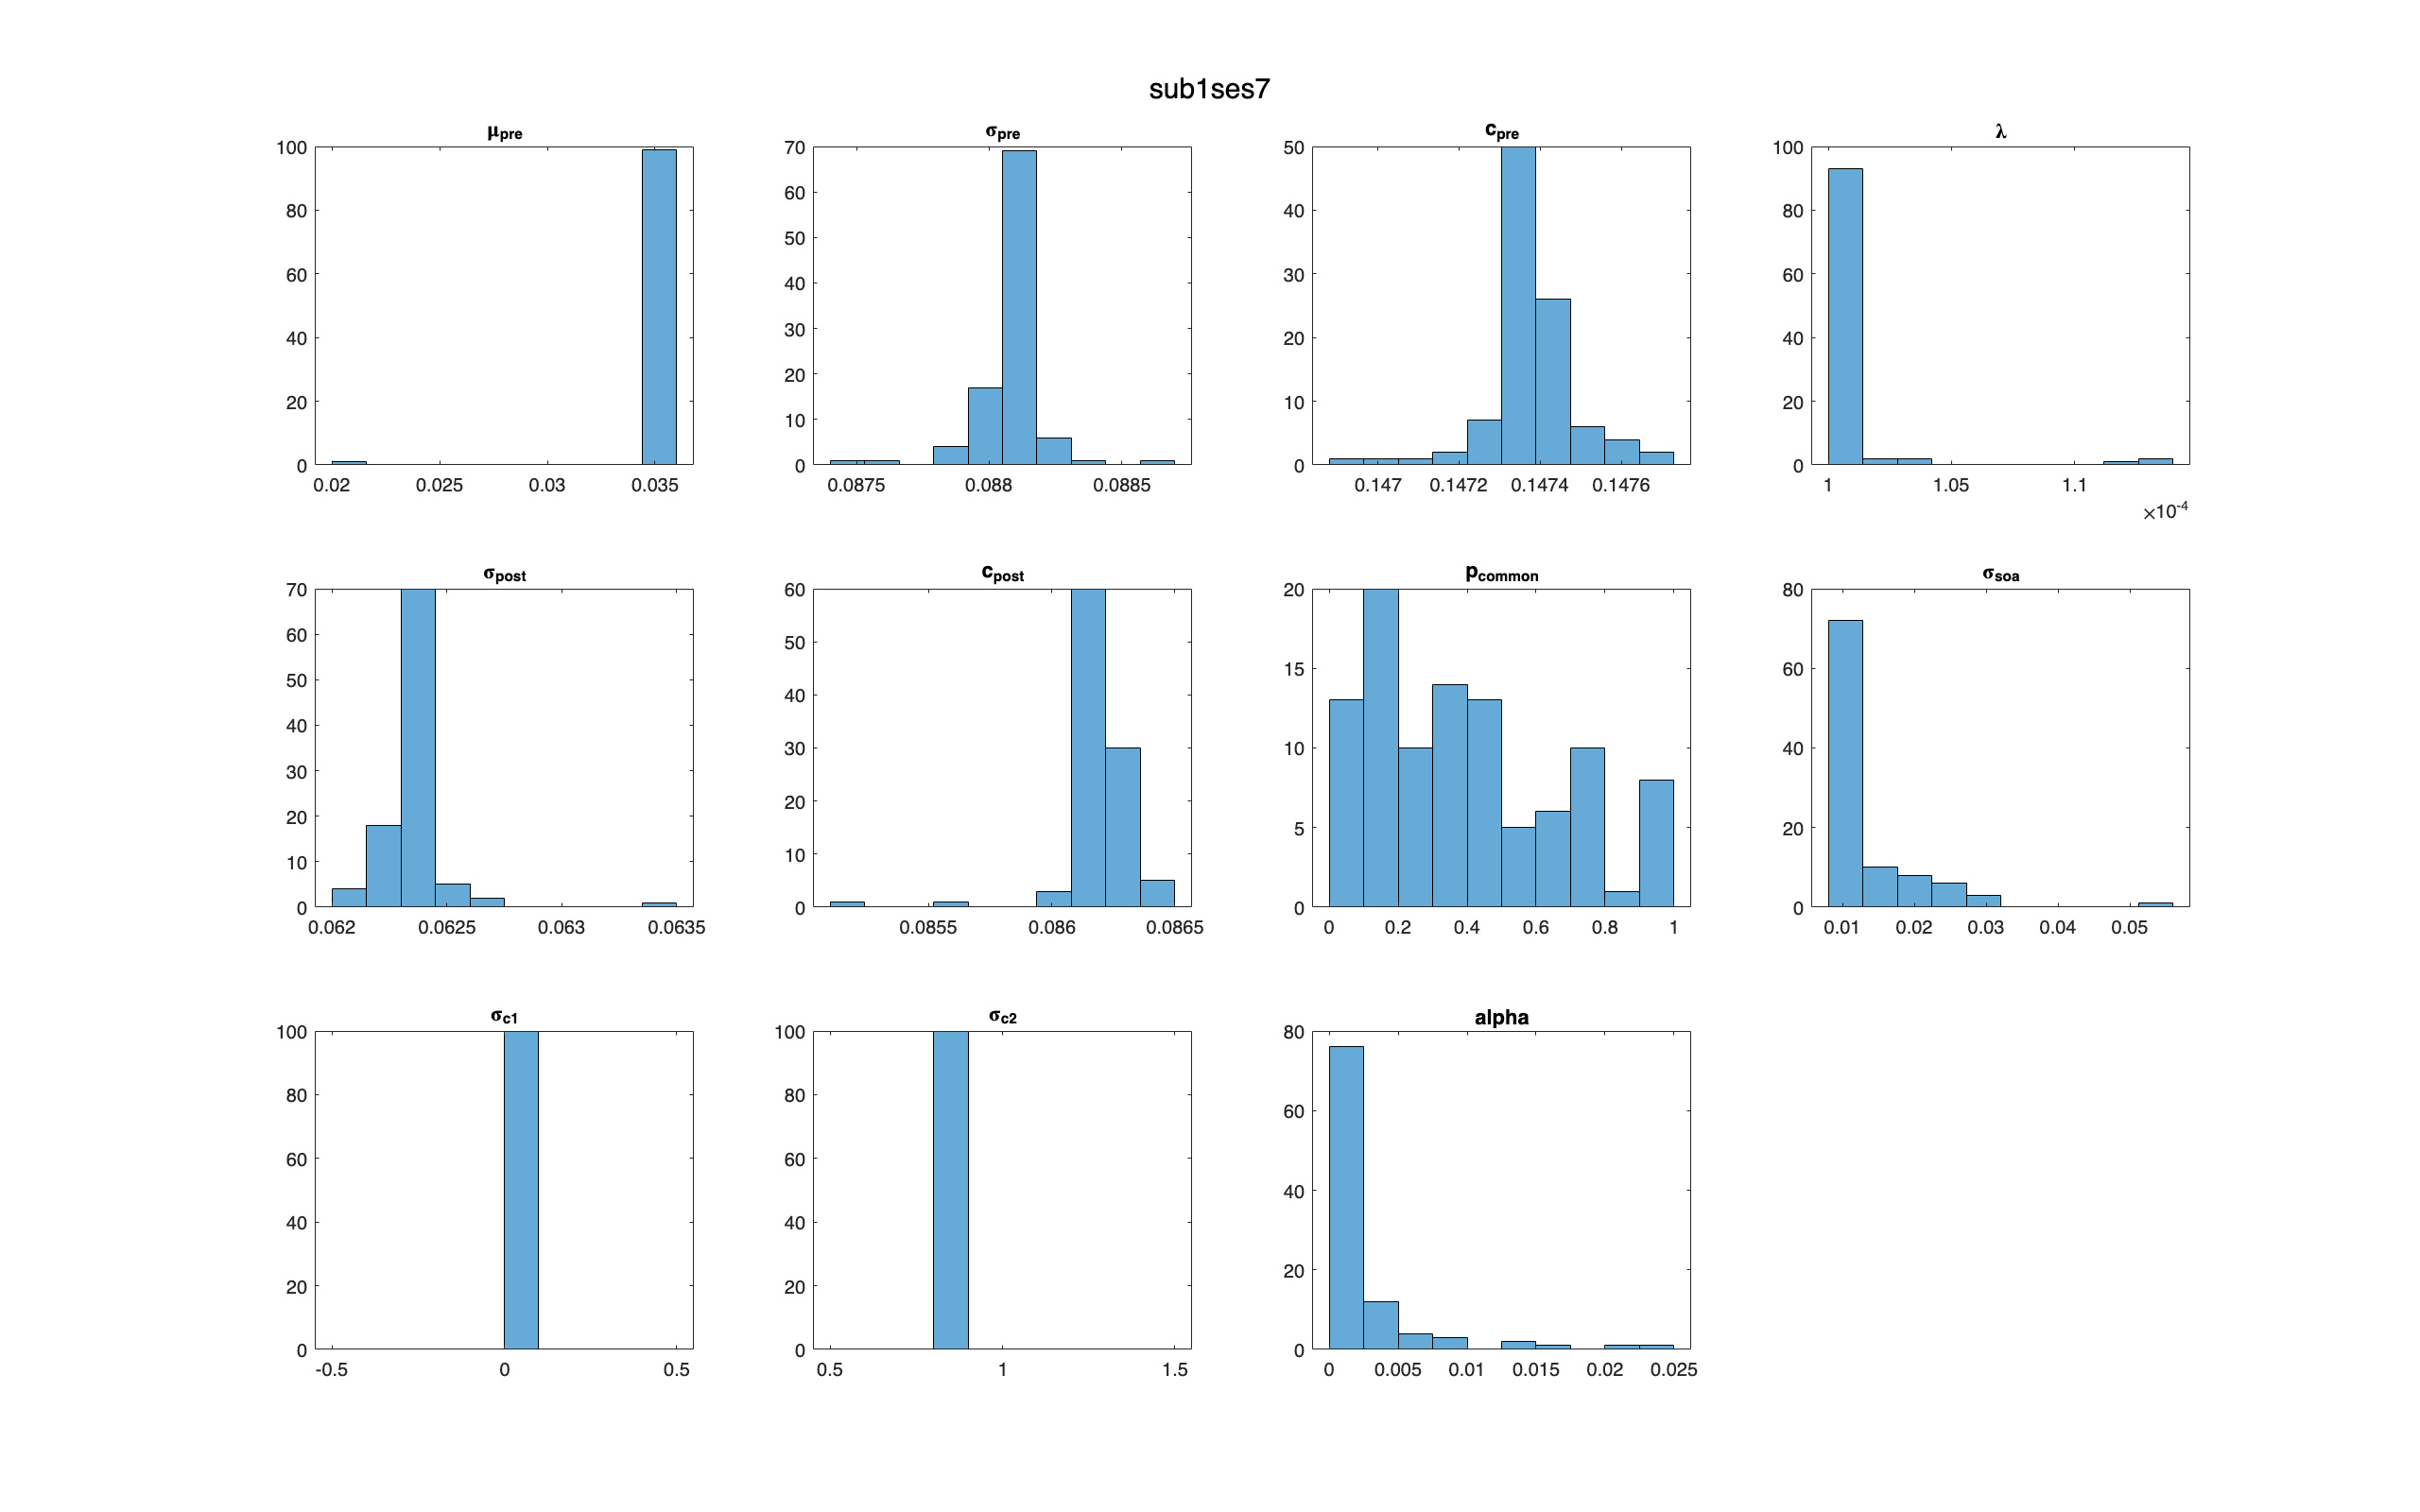

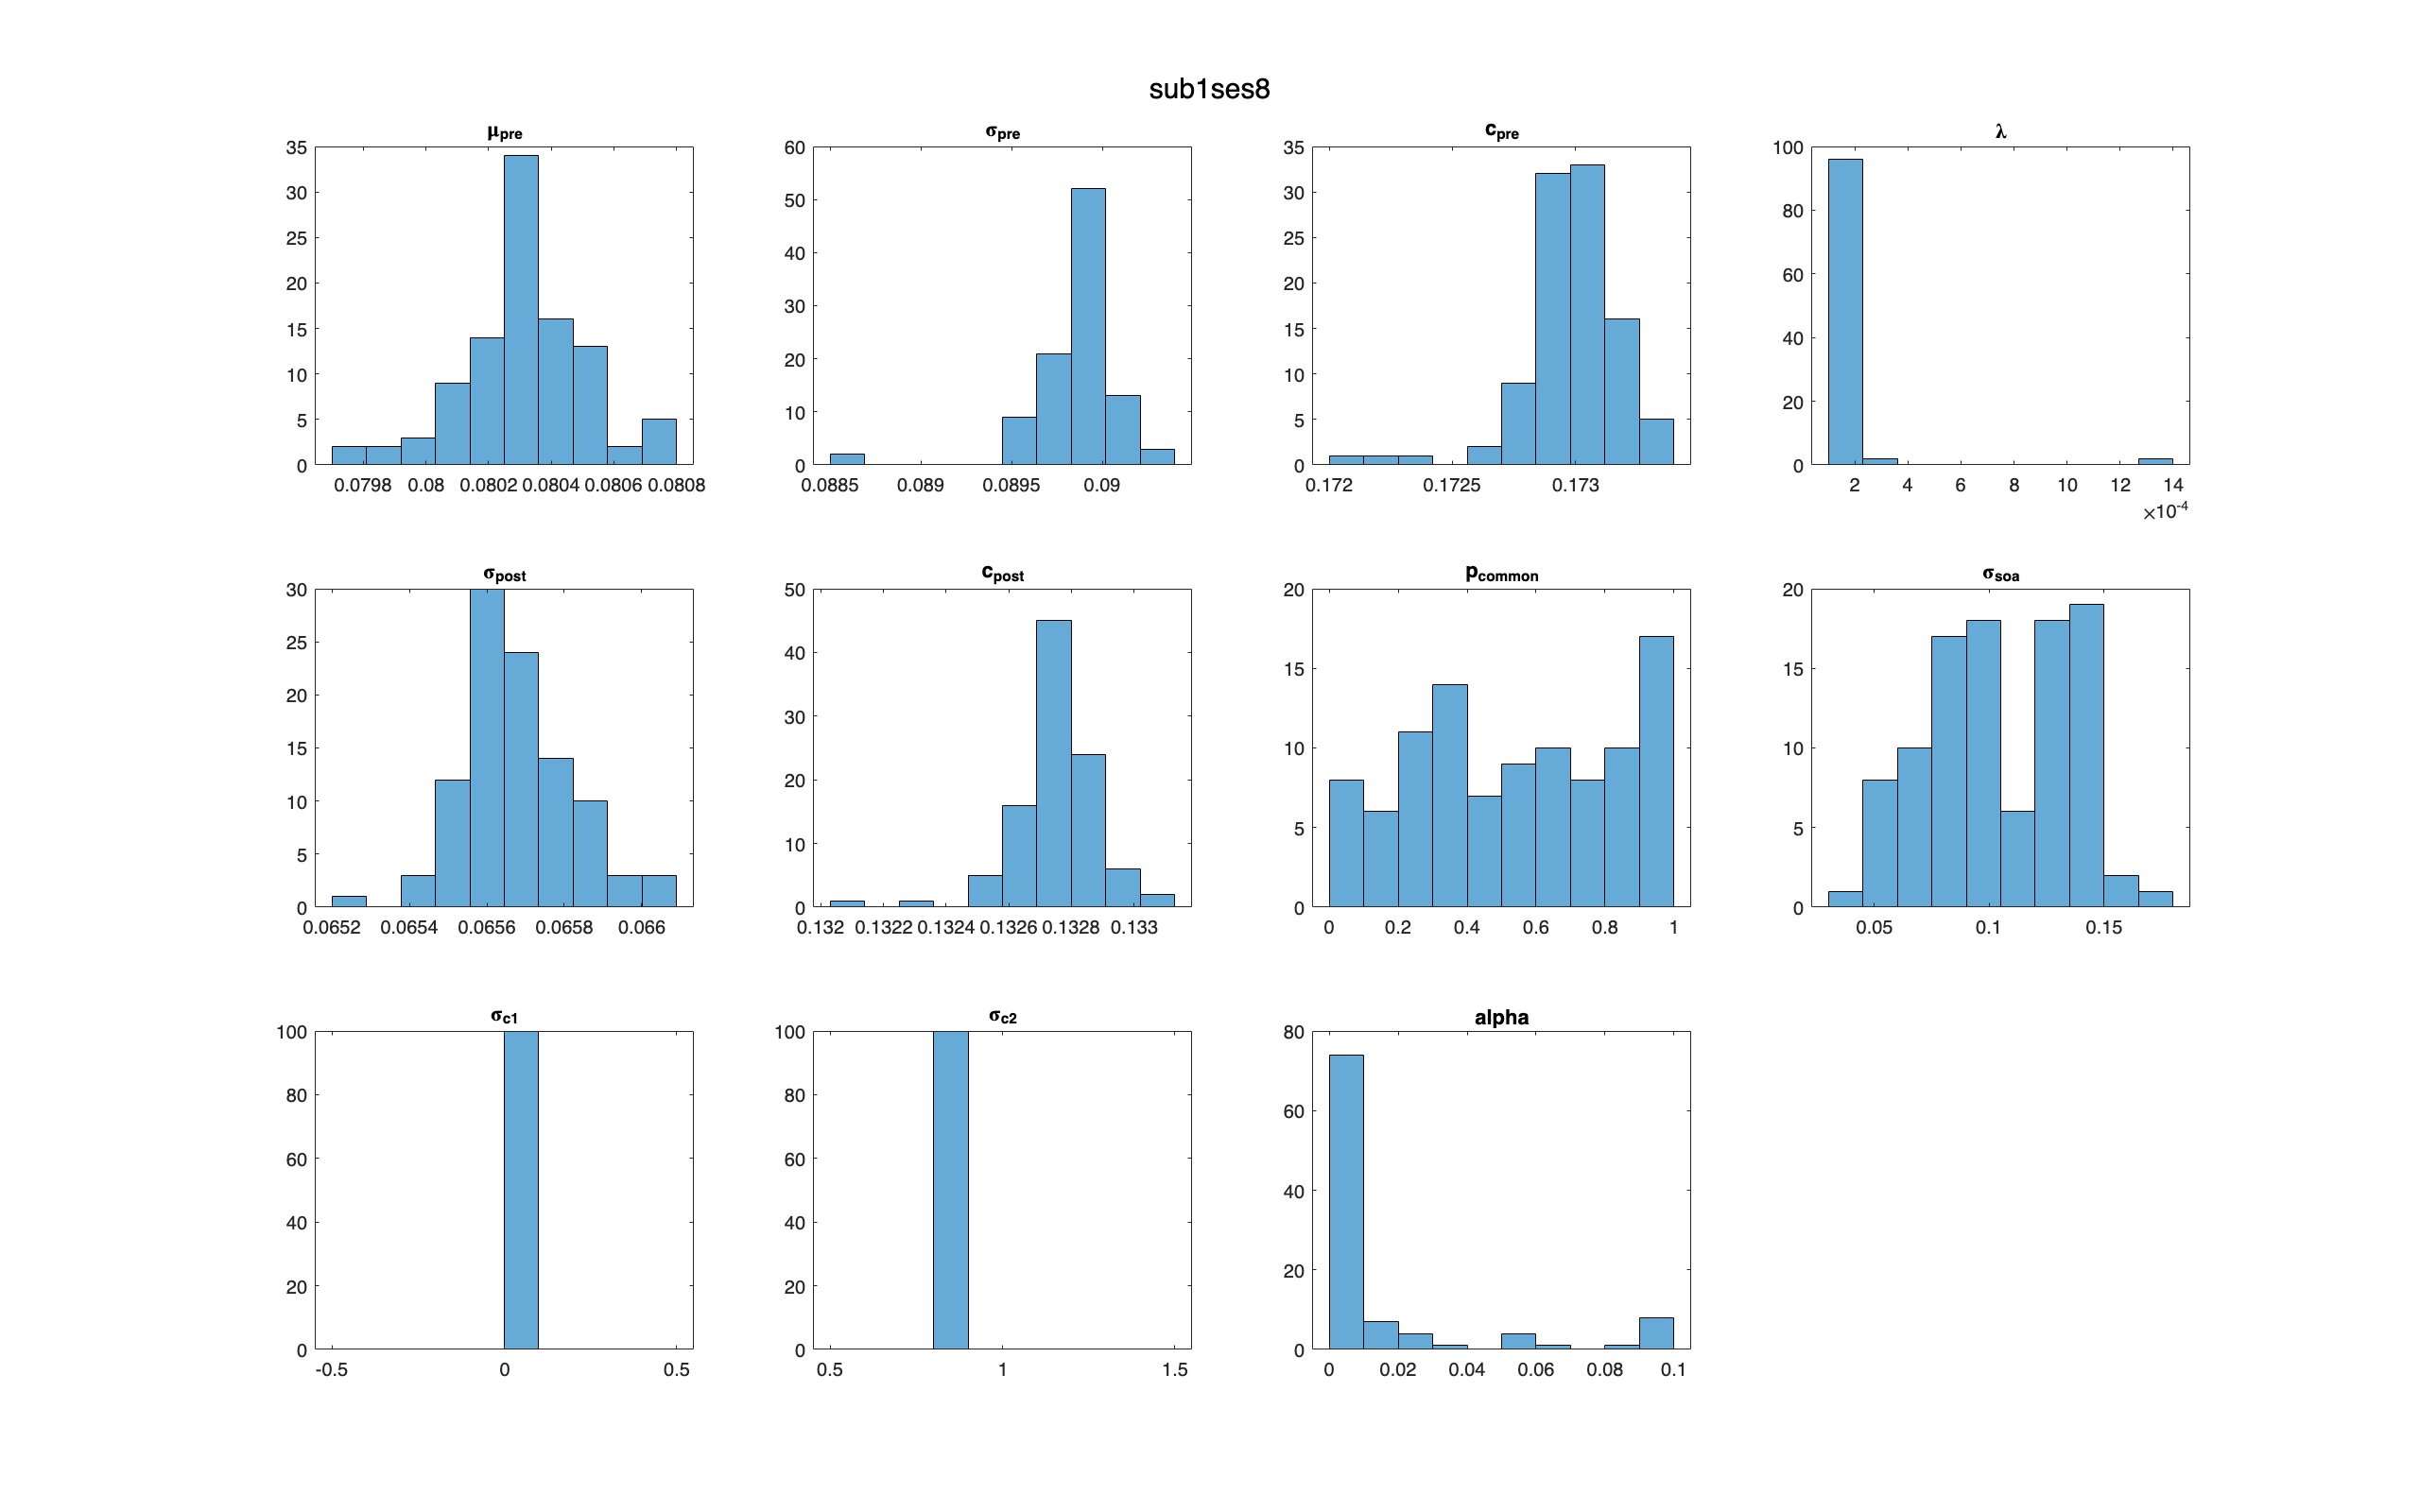

% This script takes the fitting results from a1_modelFitting.m and plots
% the distribution of fitted parameters (as we fitted 100 times for each
% session, each subject)


clear all; clc;

load("a1_modelFittingResults_v2.mat")

all_sub = 1;
all_ses = 1:9;

for sub = all_sub

    for  ses = all_ses
        figure; set(gcf, 'Position', get(0, 'Screensize'));
        sgtitle(['sub' num2str(sub) 'ses' num2str(ses)])
        set(gca, 'LineWidth', 1, 'FontSize', 15)
        for i = 1:model(sub, ses).numPara
            subplot(3,4,i)
            histogram(model(sub, ses).estimatedP(:,i), 10)
            title(model(sub, ses).paraID{i})
        end

    end
end


%% plot best fitting p_common for every subject